# LAB4: Processat Morfològic d'Imatges I (Imatges binàries)

Un element estructurant no deixa de ser una matriu d'uns i ceros, que el que fa es servir de model per aplicar operacions. Sobre un element estructurant donat, podem aplicar diferents operacions de transformació.

L'element estructurant es pot aplicar tant al fons(normalment negre) o a l'imatge en si (normalment blanc).

strel(); %generar elements estructurants.

ans = strel is a arbitrary shaped structuring element with properties:

      Neighborhood: []
    Dimensionality: 2


### Dilatació

El que es fa es aplicar l'element estructurant, pixel a pixel i per cada pixel es pintan tots els veins del element estructurant que estan a 1. **S'expandeix el color blanc**

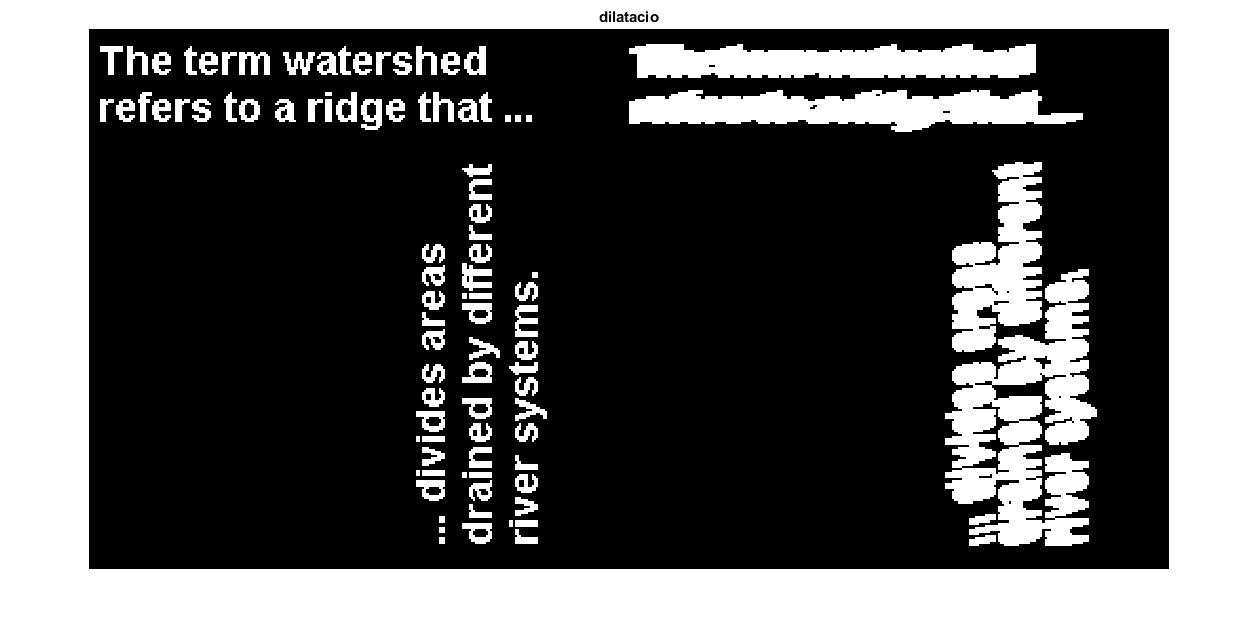

BW = imread('text.png');
element_estructurant = strel('line', 11, 9);

BW_dilated = imdilate(BW, element_estructurant);
montage({BW, BW_dilated})
title('dilatacio')

### Erosió

S'aplica igual l'EE, pero s'esborran els pixels corresponents a un 1. **Es contrau el color blanc**

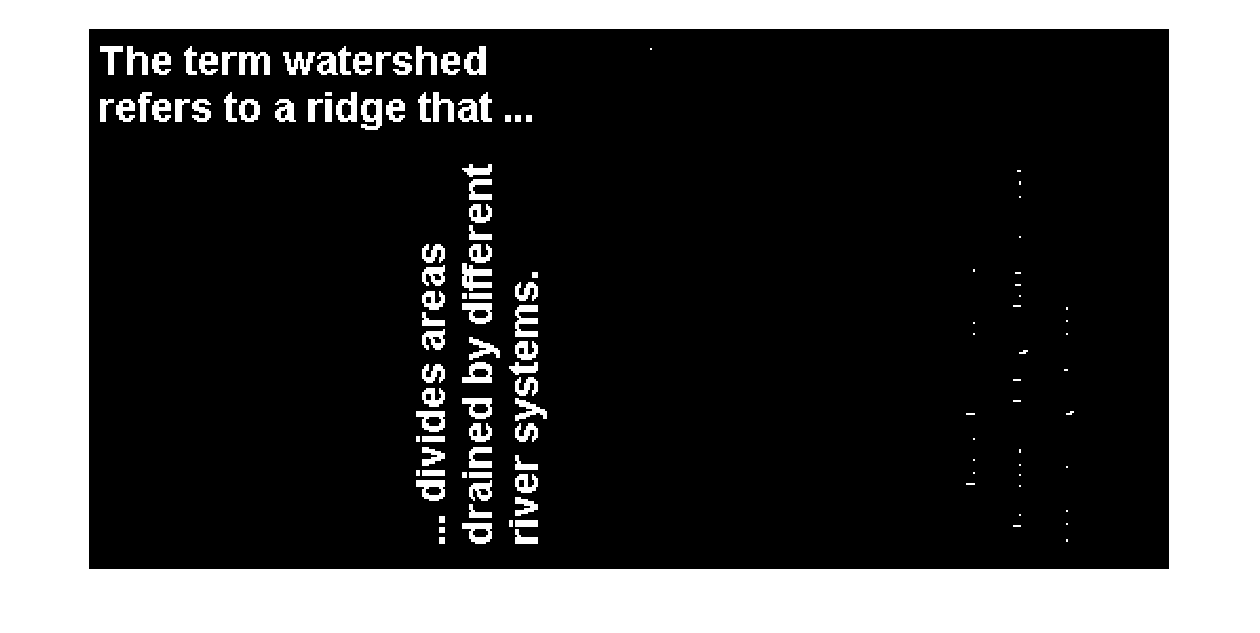

BW_erode = imerode(BW, element_estructurant);
montage({BW, BW_erode})

### Opening

Es tracta d'una erosió seguida d'una dilatació. **El resultat fa que despareguin els detalls més petits**.

En aquest cas estem eliminant els cercles amb radi inferior a 5.

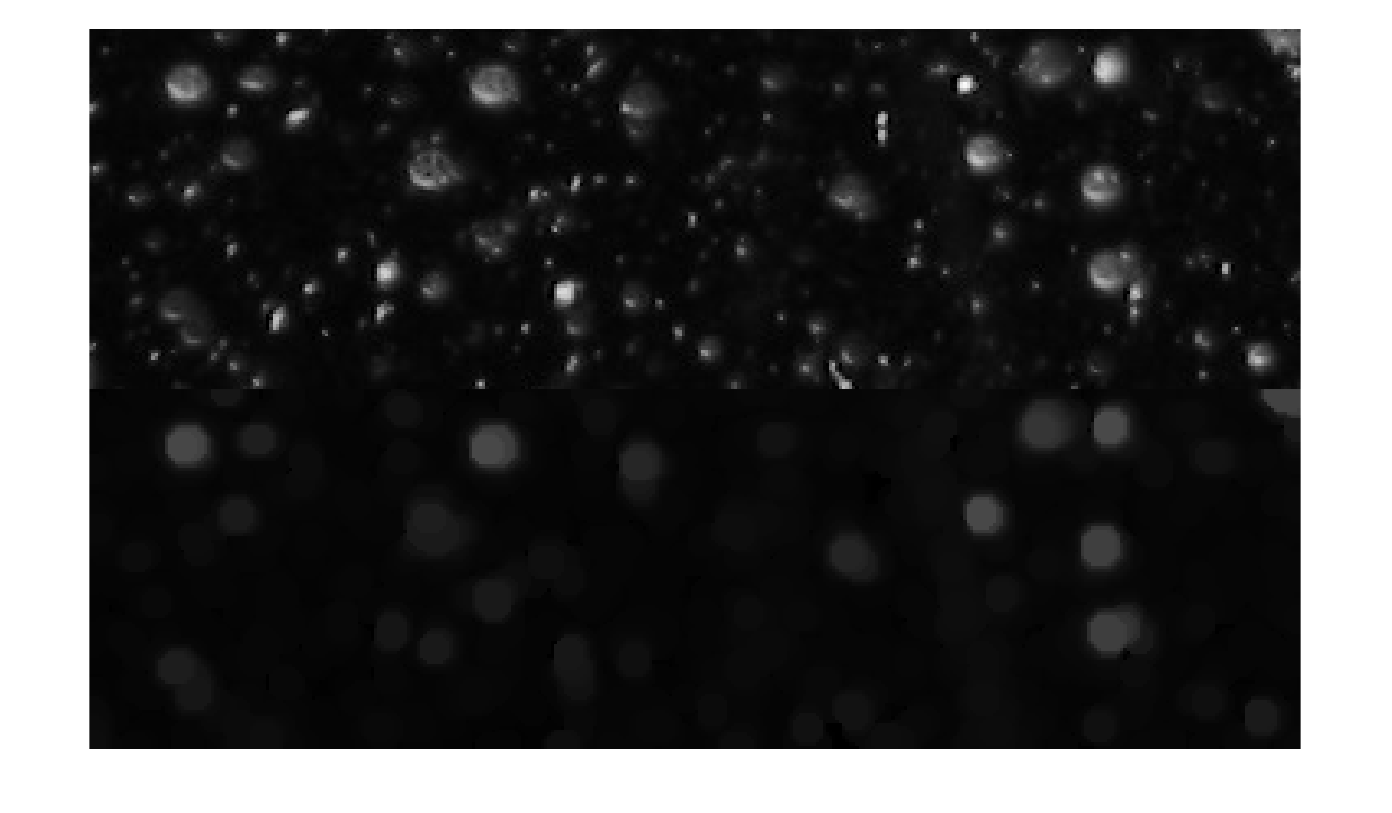

original = imread('snowflakes.png');
se = strel('disk', 5);
after_open= imopen(original, se);
montage({original, after_open})

### Closing

Es tracta d'una dilatació seguida d'una erosió. **Elimina petites estructures del "fons".**

En aquest cas, juntem les regions blanques de la imatge

radioEE= 50

radioEE = 50

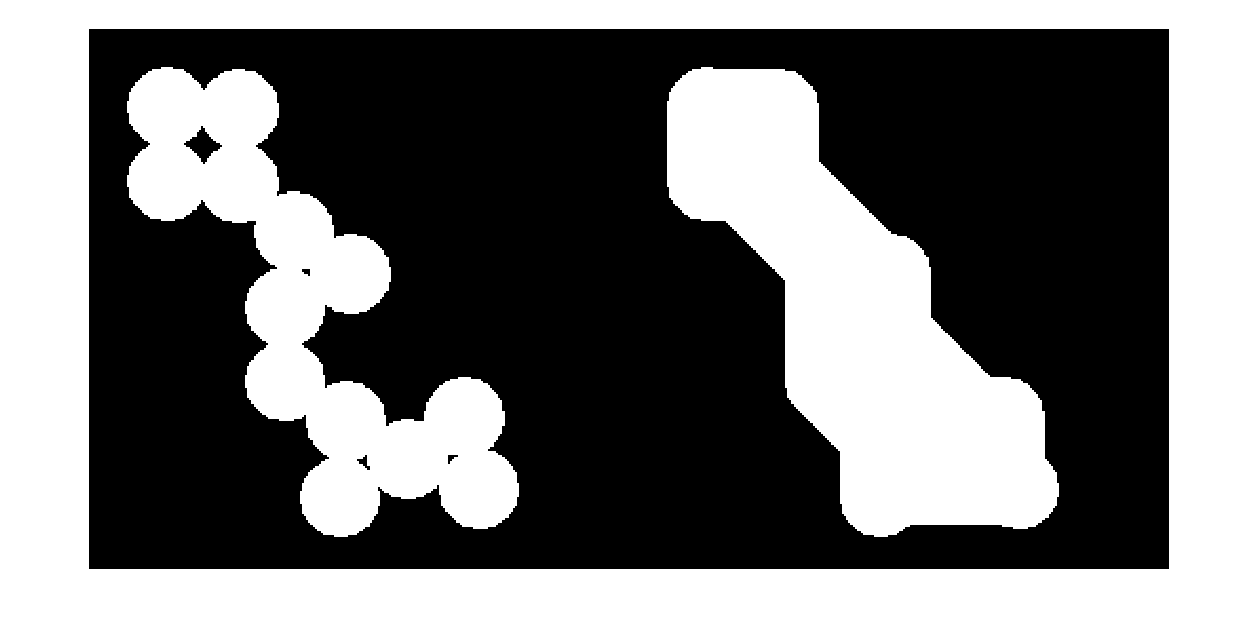

circles = imread('circles.png');
se = strel('disk', radioEE);
after_close = imclose(circles, se);
montage({circles, after_close})

### Reconstrucció - Emplena regions/forats

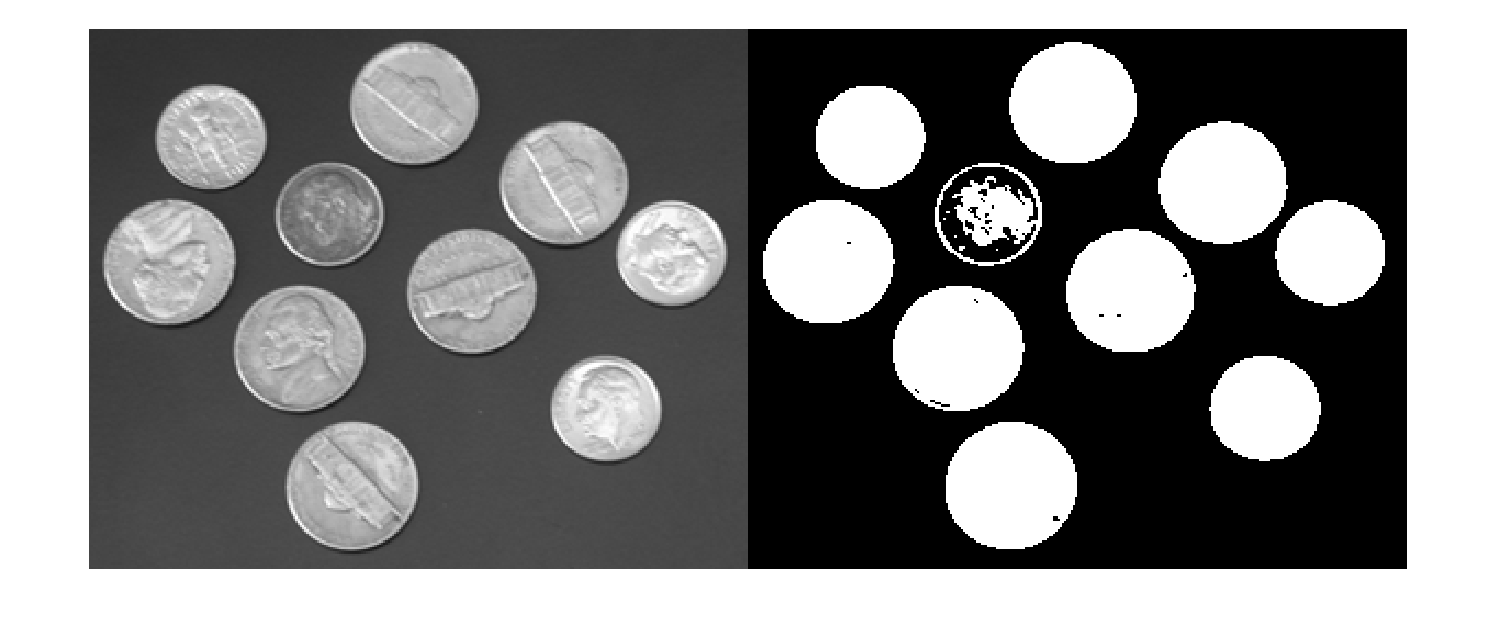

monedas = imread('coins.png');
BWmonedas = imbinarize(monedas);
montage({monedas, BWmonedas}) %hay imperfecciones en las monedas binarizadas.

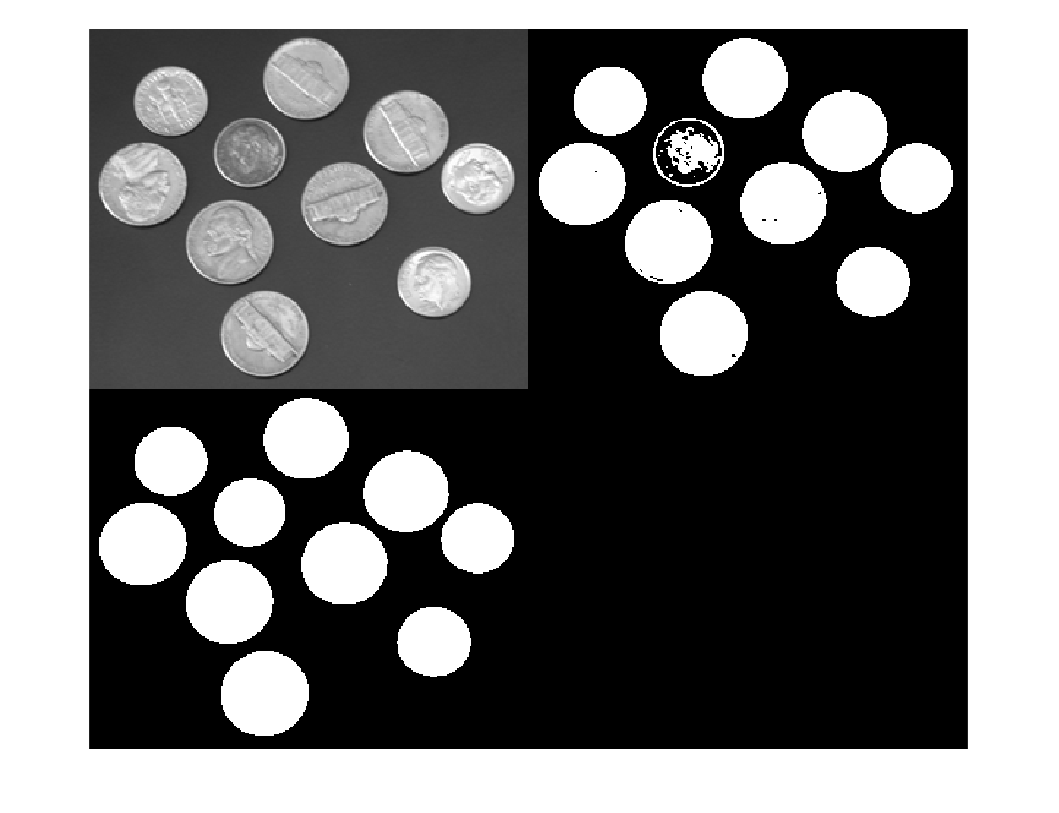

monedasFill = imfill(BWmonedas, 'holes');
montage({monedas, BWmonedas, monedasFill}) %hay imperfecciones en las monedas binarizadas.

### Erosió definitiva - ultimate erode

Limita los elementos de la imagen al mínimo.

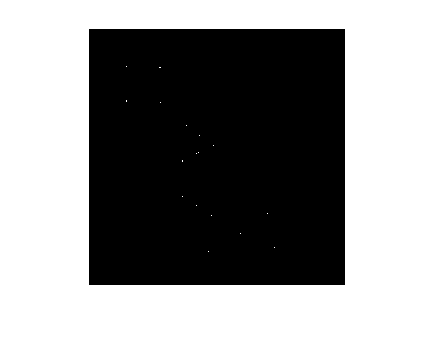

ultimateErodeCircles = bwulterode(circles);
figure, imshow(ultimateErodeCircles)

## Etiquetar objectes connectats

Funciones para encontrar el numero de objetos.

%[labeledImage, numberOfObjects] = bwlabel(binIMG);
%cc = bwconncomp(binIMG, 4);

# LAB 6: Processat morfològic d'imatges (Imatges multinivell)

Es poden veure les imatges multinivell com models d'elevació de terreny. Existeixen dos maneres de treballar-hi:

- Descomposició per llindars : Descomposició en varies imatges binaries (cross sections). Una cross-section t ve donada pels píxels de valor major o igual que t.

- Umbra d'una funció: Punts que queden per sota d'una funció donada.

Les aplicacions de les operacions open i close canvien en aquest tipus d'imatges.

- Open : Filtrat de soroll impulsional

Per aquets filtres, definim els residus com la part de la imatge eliminada al filtrar, tenim dos tipus:

- Gradient morfologic

- Top-hat